%Load dataset for CT scan of frozen cadaver and MRI scan
data = load("visiblehuman.mat");
dataCT = data.head_frozen;
dataMRI = data.head_mri;

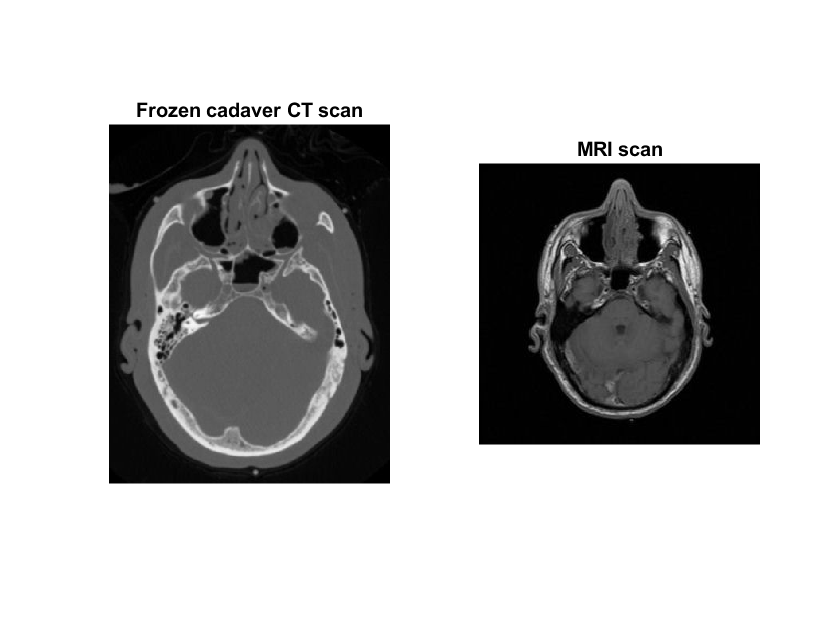

%Visualize the images
figure();
subplot(1, 2, 1);
imshow(dataCT), title("Frozen cadaver CT scan");
subplot(1, 2, 2);
imshow(dataMRI), title("MRI scan");

%Compute the center of mass for the 2 images using the implemented function
%CenterOfMass
CTDouble = im2double(dataCT);
MRIDouble = im2double(dataMRI);
comCT = CenterOfMass(CTDouble)

comCT =    248
   173


comMRI = CenterOfMass(MRIDouble)

comMRI =    128
   131


% coompute the covariance matrix for two images using implemented function 
% covMat
covCT = covMat(CTDouble, comCT)

covCT = 	1.0e+04 *

    1.0547    0.0079
    0.0079    0.6769


covMRI = covMat(MRIDouble, comMRI)

covMRI = 	1.0e+03 *

    2.9121   -0.0064
   -0.0064    1.9013



[Vct,Dct] = eig(covCT)

Vct =     0.9998   -0.0209
    0.0209    0.9998


Dct = 	1.0e+04 *

    1.0549         0
         0    0.6767


[Vmri,Dmri] = eig(covMRI)

Vmri =     1.0000    0.0064
   -0.0064    1.0000


Dmri = 	1.0e+03 *

    2.9122         0
         0    1.9012



pointCT = principalAxes(comCT, Vct, Dct)

pointCT =    248   351   145   246   250
   173   175   171   255    91


pointMRI = principalAxes(comMRI, Vmri, Dmri)

pointMRI =    128   182    74   128   128
   131   131   131   175    87


% transformation
[s_hat, R_hat, t_hat] = Similarity_Transf (pointCT, pointMRI);
X = (1:size(dataCT, 1))';
Y = (1:size(dataCT, 2))';
[xGrid, yGrid] = meshgrid(X, Y);
template = [xGrid(:), yGrid(:)]';
changedCoor = newCoor(template, R_hat, s_hat, t_hat);
reshapedX = reshape(changedCoor(2,:), size(yGrid));
reshapedY = reshape(changedCoor(1,:), size(xGrid));
MRI_to_CT = interp2(MRIDouble, reshapedX, reshapedY, 'spline');
image = twoChanIm(MRI_to_CT', CTDouble);

size of images are not the same

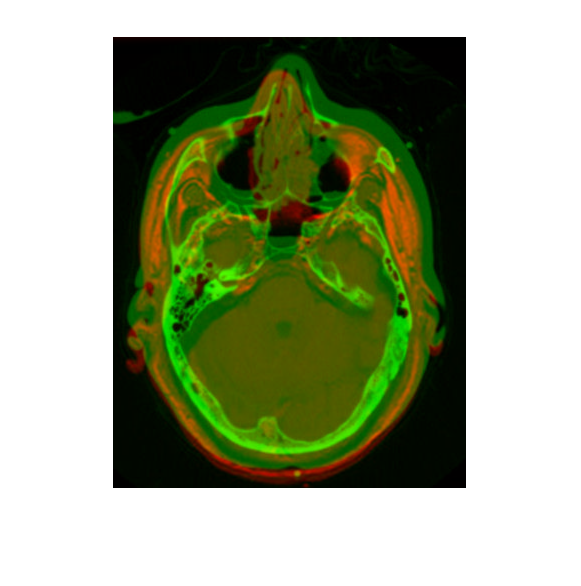

figure()
imshow(image ,[])

im1 = dataCT;
im2 = MRI_to_CT';
MI = zeros(80);
for i = 1:size(MI, 1)
    for j = 1:size(MI, 1)
        changedCoor = newCoor(template, R_hat, s_hat, t_hat - [i-40 j-40]');
        reshapedX = reshape(changedCoor(2,:), size(yGrid));
        reshapedY = reshape(changedCoor(1,:), size(xGrid));
        MRI_to_CT = interp2(MRIDouble, reshapedX, reshapedY, 'spline');
        im2 = MRI_to_CT';
        jointHistogram = histogram2(double(im1(:)'), double(im2(:)'));
        jointPdf = jointHistogram / sum(jointHistogram(:));
        firstMarginalPdf = sum(jointPdf, 1);
        secondMarginalPdf = sum(jointPdf, 2);
        MI(i,j) = log(jointPdf(:) + eps )' * jointPdf(:) - ...
            log(firstMarginalPdf(:) + eps )' * firstMarginalPdf(:) - ...
            log(secondMarginalPdf(:) + eps )' * secondMarginalPdf(:);
    end
end

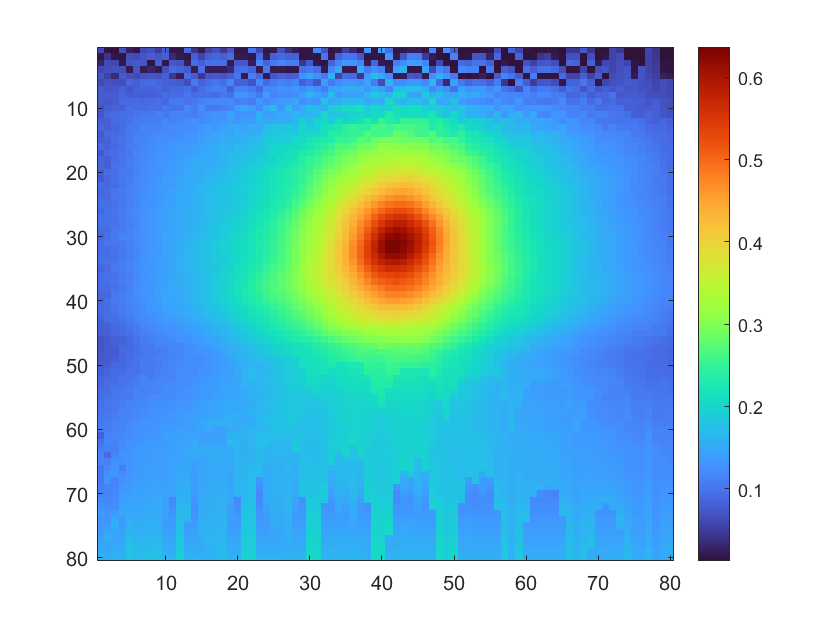

figure()
colormap('turbo')
imagesc(MI)
colorbar

[M, I] = max(max(MI, [], 1))

M = 0.6366

I = 42

[M1, I1] = max(max(MI, [], 2))

M1 = 0.6366

I1 = 31

changedCoor = newCoor(template, R_hat, s_hat, t_hat - [I1-40 I-40]');
reshapedX = reshape(changedCoor(2,:), size(yGrid));
reshapedY = reshape(changedCoor(1,:), size(xGrid));
MRI_to_CT = interp2(MRIDouble, reshapedX, reshapedY, 'spline');
image = twoChanIm(MRI_to_CT', CTDouble);

size of images are not the same

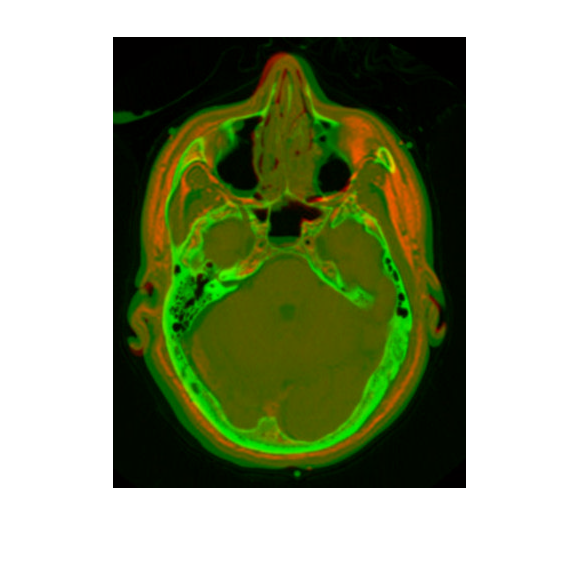

figure()
imshow(image ,[])

M2 = 0.3851

I2 = 16

vec =    -15   -14   -13   -12   -11   -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15


size of images are not the same

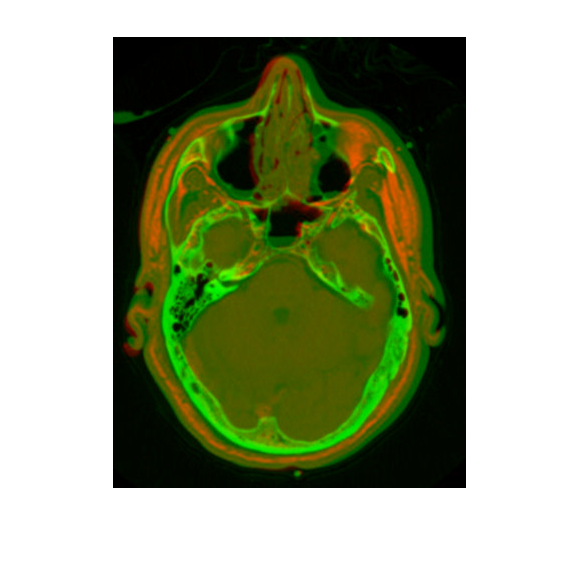

[s_hat, R_hat, t_hat] = Similarity_Transf (pointCT, pointMRI);
MI_rot = (-15:1:15);
for i = 1:length(MI_rot)
    R_hat = [cos(MI_rot(i)), -sin(MI_rot(i)); sin(MI_rot(i)), cos(MI_rot(i))];
    changedCoor = newCoor(template, R_hat, s_hat, t_hat);
    reshapedX = reshape(changedCoor(2,:), size(yGrid));
    reshapedY = reshape(changedCoor(1,:), size(xGrid));
    MRI_to_CT = interp2(MRIDouble, reshapedX, reshapedY, 'spline');
    im2 = MRI_to_CT';
        jointHistogram = histogram2(double(im1(:)'), double(im2(:)'));
        jointPdf = jointHistogram / sum(jointHistogram(:));
        firstMarginalPdf = sum(jointPdf, 1);
        secondMarginalPdf = sum(jointPdf, 2);
        MI_rot(i) = log(jointPdf(:) + eps )' * jointPdf(:) - ...
            log(firstMarginalPdf(:) + eps )' * firstMarginalPdf(:) - ...
            log(secondMarginalPdf(:) + eps )' * secondMarginalPdf(:);
   
end